# View Sample Points

This script generates a sine wave with a single tone at `f` Hz. In this activity, you'll modify the frequency value and sample rate to see effects of aliasing.

In the time-domain plot, the blue line shows a smooth, curved sine wave. This might be how you are accustomed to seeing sine waves.

Discrete-time signals in the time domain can look strange. In the plot, the red points are the sampled points, and the black lines connect them. You may not recognize the sampled points as a sine wave. But if you sample fast enough, the frequency-domain plot will still show the correct frequency.

The frequency-domain plot is below the time-domain plot. Notice that the frequency content is correctly located at the `f` value.

In the frequency-domain plot, notice that the frequency content isn't located at the slider value for `f`.

f = 2;
fs = 3;

tfixed = 0 : 1/100 : 100;
yfixed = sin(2*pi*f*tfixed);
plot(tfixed, yfixed)

tmoving = 0 : 1/fs : 100;
ymoving = sin(2*pi*f*tmoving);

Time-domain plot

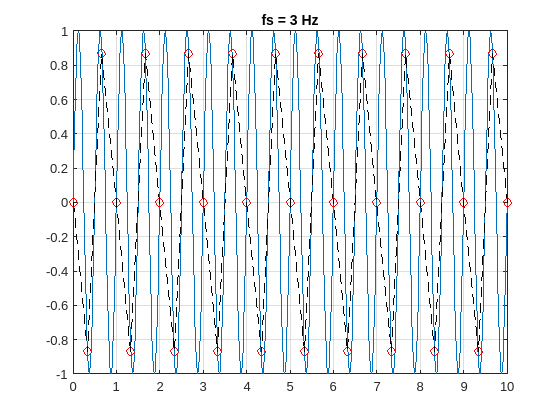

hold on
grid on
movingStems = plot(tmoving, ymoving, "ro");
movingLine  = plot(tmoving, ymoving, "k--");
hold off
xlim([0 10])
t = title("fs = " + fs + " Hz");

Frequency-domain plot

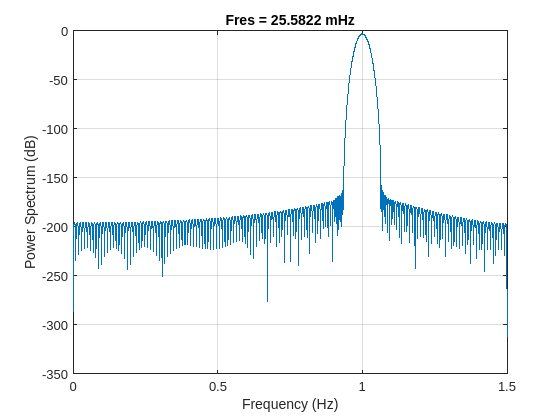

pspectrum(ymoving, fs)